# Digital Modulation System

% INSTRUCTIONS
% Modulating Signal (show graph)
% Encode the signal
    % Manchester, NRZ, RZ
% Modulate the signal (show graph, constellation diagram)
    % 2BPSK,QPSK, 16PSK, 4FSK, 4QAM, 8QAM, 16QAM
% Add noise
    % SNR = 5dB, 10dB, 70dB
% Demodulate the Signal
% Compute for BER
% Recover the received signal

## Modulating Signal (display graph)

clear all; clc; clf;

% input audio signal in time domain
[y, Fs] = audioread("TestAudio.wav");
info = audioinfo("TestAudio.wav")

info = struct with fields:
             Filename: '/Users/binisya/Documents/Charmbix-COMMANA-FP/TestAudio.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 163776
             Duration: 3.4120
                Title: 'New Recording 2'
              Comment: []
               Artist: []
        BitsPerSample: 16


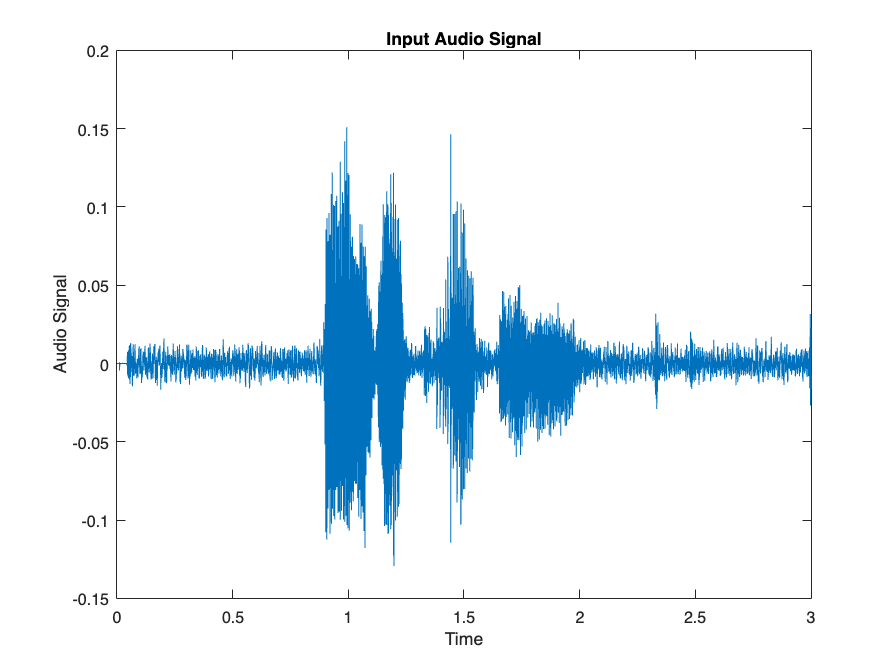


starttime = 0;
endtime = 3;
startsample = starttime*Fs + 1;
endsample = endtime*Fs;

y = y(startsample:endsample+1);
t = starttime : 1/Fs : endtime;

% convert to integer
A = round(y*127+128);

clf;
figure
plot(t,y); xlabel('Time'); ylabel('Audio Signal'); title('Input Audio Signal')

### Converting the signal to base-N

% base-2
base2 = dec2base(A,2);

% base-4
base4 = dec2base(A,4);

% base-8
base8 = dec2base(A,8);

% base-16
base16 = dec2base(A,16);

### Arranging to a single column vector

% base-2
forbase2 = reshape(base2',[],1);
forbase2 = base2dec(forbase2,2);

% base-4
forbase4 = reshape(base4',[],1);
forbase4 = base2dec(forbase4,4);

% base-8
forbase8 = reshape(base8',[],1);
forbase8 = base2dec(forbase8,8);

% base-16
forbase16 = reshape(base16',[],1);
forbase16 = base2dec(forbase16,16);

## Encoding the signal

### Test Signal

bits = getByteStreamFromArray(("TestAudio.wav"));

### Manchester

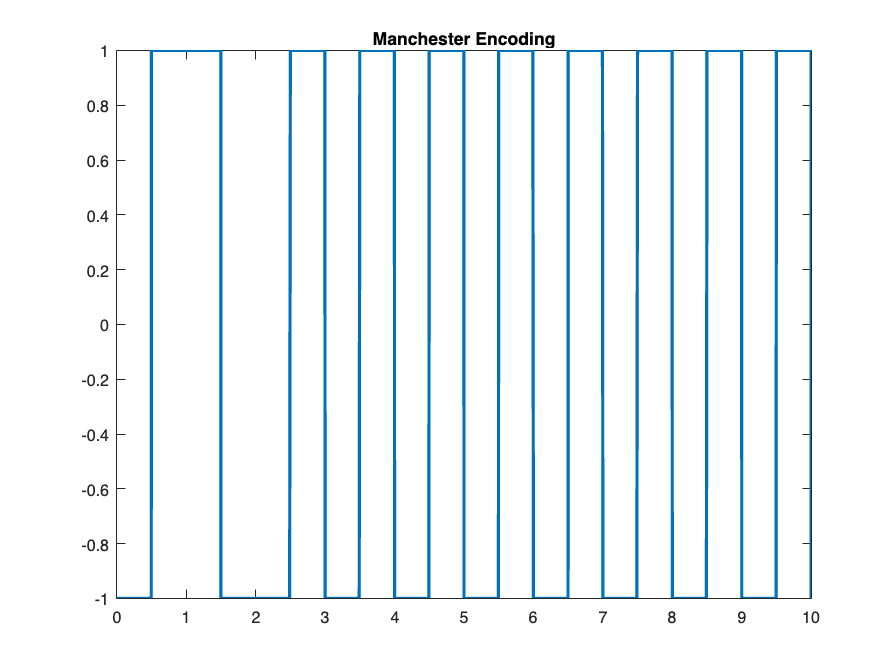

% Manchester encoding
bitrate = 1;
n = 1000;
T = length(bits)/bitrate;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i=1:length(bits)
  if bits(i)==1
    x((i-1)*n+1:(i-1)*n+n/2) = 1;
    x((i-1)*n+n/2:i*n) = -1;
  else
    x((i-1)*n+1:(i-1)*n+n/2) = -1;
    x((i-1)*n+n/2:i*n) = 1;
  end
end
plot(t, x, 'Linewidth', 2); title('Manchester Encoding')
xlim([0 10]);

### NRZ

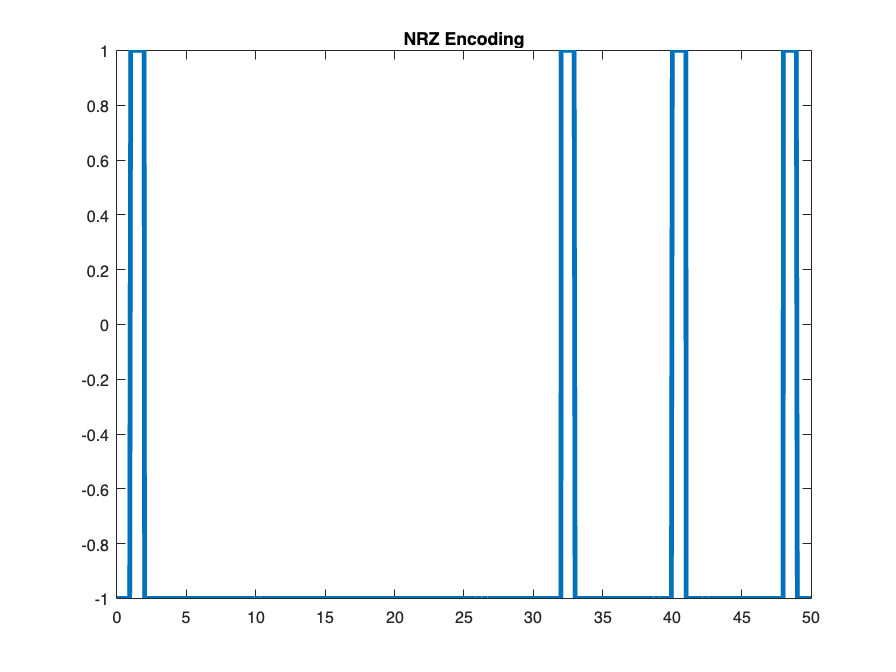

% NRZ Encoding
bitrate = 1;
n = 1000;
T = length(bits)/bitrate;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i=1:length(bits)
  if bits(i)==1
    x((i-1)*n+1:i*n) = 1;
  else 
      x((i-1)*n+1:i*n) = -1;
  end
end
plot(t, x, 'Linewidth', 3); title('NRZ Encoding')
xlim([0 50])

### RZ

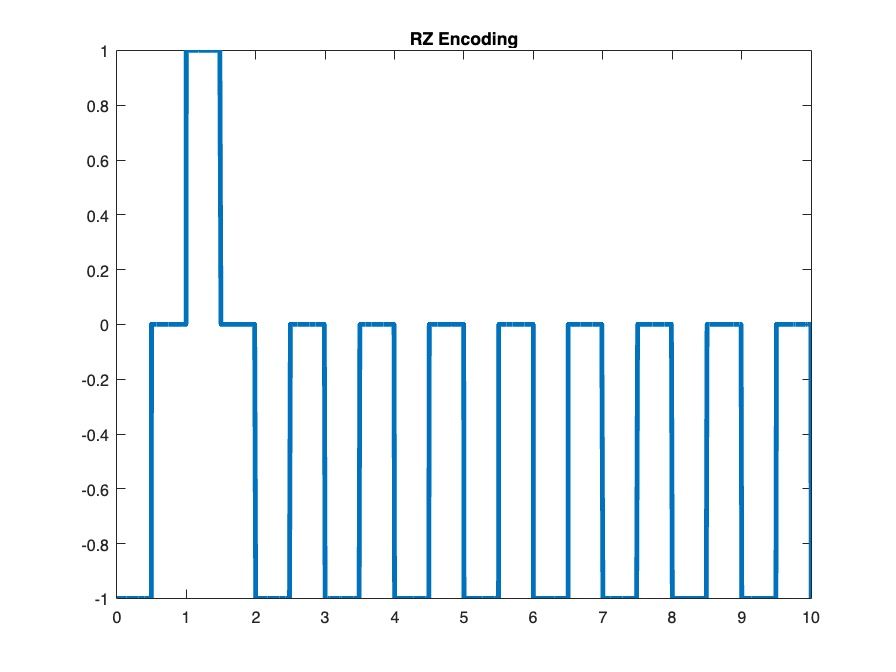

% RZ Encoding
bitrate = 1;
n = 1000;
T = length(bits)/bitrate;
N = n*length(bits);
dt = T/N;
t = 0:dt:T;
x = zeros(1,length(t));
for i=1:length(bits)
  if bits(i)==1
    x((i-1)*n+1:(i-1)*n+n/2) = 1;
  else x((i-1)*n+1:(i-1)*n+n/2) = -1;
  end
end
plot(t, x, 'Linewidth', 3); title('RZ Encoding')
xlim([0 10])

## Modulating the signal

### 2PSK

M = 2;
two_psk = pskmod(forbase2, M);

### 16PSK

M = 16;
sixteen_psk = pskmod(forbase16, M);

### 4FSK

M = 4;
freq_sep = 10000;    % assumed value 
nsamp = 10;      % assumed value 
four_fsk = fskmod(forbase4, M, freq_sep, nsamp, Fs);

### 4QAM

M = 4;
four_qam = qammod(forbase4, M);

### 8QAM

M = 8;
eight_qam = qammod(forbase8, M);

### 16QAM

M = 16;
sixteen_qam = qammod(forbase16, M);

## Adding noise 

### SNR = 5dB

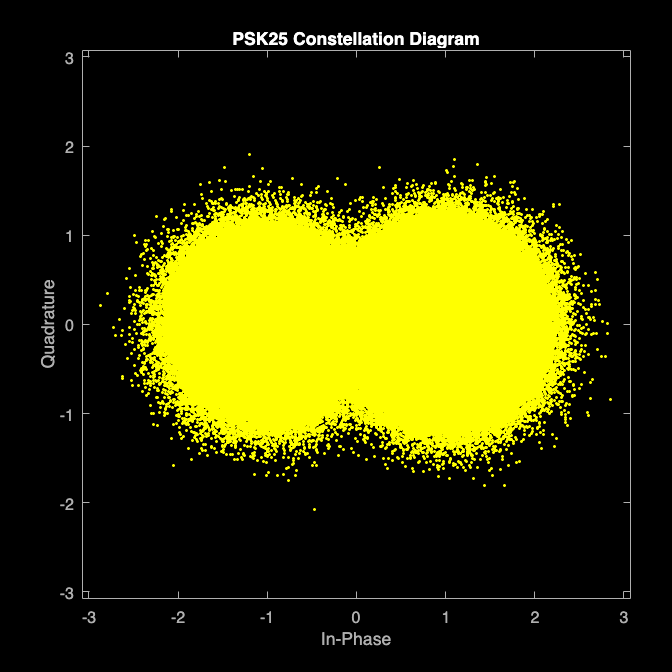

clf
five_snr = 5;
psk25 = awgn(two_psk,five_snr);

% Plot constellation diagram
scatterplot(psk25);
title('PSK25 Constellation Diagram');


psk165 = awgn(sixteen_psk,five_snr);
% Plot constellation diagram
scatterplot(psk165);
title('PSK165 Constellation Diagram');


fsk45 = awgn(four_fsk,five_snr);
% Plot constellation diagram
scatterplot(fsk45);
title('FSK45Constellation Diagram');


qam45 = awgn(four_qam,five_snr);
% Plot constellation diagram
scatterplot(qam45);
title('QAM45 Constellation Diagram');


qam85 = awgn(eight_qam,five_snr);
% Plot constellation diagram
scatterplot(qam85);
title('QAM85 Constellation Diagram');


qam165 = awgn(sixteen_qam,five_snr);
% Plot constellation diagram
scatterplot(qam165);
title('QAM165 Constellation Diagram');

### SNR = 10dB

ten_snr = 10;
psk210 = awgn(two_psk,ten_snr);
% Plot constellation diagram
scatterplot(psk210);
title('PSK210 Constellation Diagram');


psk1610 = awgn(sixteen_psk,ten_snr);
% Plot constellation diagram
scatterplot(psk1610);
title('PSK1610 Constellation Diagram');


fsk410 = awgn(four_fsk,ten_snr);
% Plot constellation diagram
scatterplot(fsk410);
title('FSK410 Constellation Diagram');


qam410 = awgn(four_qam,ten_snr);
% Plot constellation diagram
scatterplot(qam410);
title('QAM410 Constellation Diagram');


qam810 = awgn(eight_qam,ten_snr);
% Plot constellation diagram
scatterplot(qam810);
title('QAM810 Constellation Diagram');


qam1610 = awgn(sixteen_qam,ten_snr);
% Plot constellation diagram
scatterplot(qam1610);
title('QAM1610 Constellation Diagram');

### SNR = 70dB

seventy_snr = 70;
psk270 = awgn(two_psk,seventy_snr);
% Plot constellation diagram
scatterplot(psk270);
title('PSK270 Constellation Diagram');


psk1670 = awgn(sixteen_psk,seventy_snr);
% Plot constellation diagram
scatterplot(psk1670);
title('PSK1670 Constellation Diagram');


fsk470 = awgn(four_fsk,seventy_snr);
% Plot constellation diagram
scatterplot(fsk470);
title('FSK470 Constellation Diagram');


qam470 = awgn(four_qam,seventy_snr);
% Plot constellation diagram
scatterplot(qam470);
title('QAM470 Constellation Diagram');


qam870 = awgn(eight_qam,seventy_snr);
% Plot constellation diagram
scatterplot(qam870);
title('QAM870 Constellation Diagram');


qam1670 = awgn(sixteen_qam,seventy_snr);
% Plot constellation diagram
scatterplot(qam1670);
title('QAM1670 Constellation Diagram');

## **DEMODULATE THE SIGNAL**

**2PSK**

%SNR=5dB
demod1_2psk = pskdemod(psk25, 2);
%SNR=10dB
demod2_2psk = pskdemod(psk210, 2);
%SNR=70dB
demod3_2psk = pskdemod(psk270, 2);

**16PSK**

%SNR=5dB
demod1_16psk = pskdemod(psk165, 16);
%SNR=10dB
demod2_16psk = pskdemod(psk1610, 16);
%SNR=70dB
demod3_16psk = pskdemod(psk1670, 16);

**4FSK**

%SNR=5dB
demod1_4fsk  = fskdemod(fsk45,  4, freq_sep, nsamp, Fs);
%SNR=10dB
demod2_4fsk  = fskdemod(fsk410,  4, freq_sep, nsamp, Fs);
%SNR=70dB
demod3_4fsk = fskdemod(fsk470, 4, freq_sep, nsamp, Fs);

**4QAM**

%SNR=5dB
demod1_4qam = qamdemod(qam45, 4);
%SNR=10dB
demod2_4qam = qamdemod(qam410, 4);
%SNR=70dB
demod3_4qam = qamdemod(qam470, 4);

**8QAM**

%SNR=5dB
demod1_8qam = qamdemod(qam85, 8);
%SNR=10dB
demod2_8qam = qamdemod(qam810, 8);
%SNR=70dB
demod3_8qam = qamdemod(qam870, 8);

**16QAM**

%SNR=5dB
demod1_16qam = qamdemod(qam165, 16);
%SNR=10dB
demod2_16qam = qamdemod(qam1610, 16);
%SNR=70dB
demod3_16qam = qamdemod(qam1670, 16);

## **COMPUTE BIT ERROR RATE**

**2PSK**

%SNR=5dB
[~, ber1_2psk]  = biterr(forbase2, demod1_2psk)

ber1_2psk = 0.0059

%SNR=10dB
[~, ber2_2psk]  = biterr(forbase2, demod2_2psk)

ber2_2psk = 4.3402e-06

%SNR=70dB
[~, ber3_2psk]  = biterr(forbase2, demod3_2psk)

ber3_2psk = 0

**16PSK**

%SNR=5dB
[~, ber1_16psk]  = biterr(forbase16, demod1_16psk)

ber1_16psk = 0.1971

%SNR=10dB
[~, ber2_16psk]  = biterr(forbase16, demod2_16psk)

ber2_16psk = 0.0990

%SNR=70dB
[~, ber3_16psk]  = biterr(forbase16, demod3_16psk)

ber3_16psk = 0

**4FSK**

%SNR=5dB
[~, ber1_4fsk]  = biterr(forbase4, demod1_4fsk)

ber1_4fsk = 0

%SNR=10dB
[~, ber2_4fsk]  = biterr(forbase4, demod2_4fsk)

ber2_4fsk = 0

%SNR=70dB
[~, ber3_4fsk]  = biterr(forbase4, demod3_4fsk)

ber3_4fsk = 0

**4QAM**

%SNR=5dB
[~, ber1_4qam]  = biterr(forbase4, demod1_4qam)

ber1_4qam = 0.0060

%SNR=10dB
[~, ber2_4qam]  = biterr(forbase4, demod2_4qam)

ber2_4qam = 1.7361e-06

%SNR=70dB
[~, ber3_4qam]  = biterr(forbase4, demod3_4qam)

ber3_4qam = 0

**8QAM**

%SNR=5dB
[~, ber1_8qam]  = biterr(forbase8, demod1_8qam)

ber1_8qam = 0.0048

%SNR=10dB
[~, ber2_8qam]  = biterr(forbase8, demod2_8qam)

ber2_8qam = 3.0864e-06

%SNR=70dB
[~, ber3_8qam]  = biterr(forbase8, demod3_8qam)

ber3_8qam = 0

**16QAM**

%SNR=5dB
[~, ber1_16qam]  = biterr(forbase16, demod1_16qam)

ber1_16qam = 0.0039

%SNR=10dB
[~, ber2_16qam]  = biterr(forbase16, demod2_16qam)

ber2_16qam = 1.7361e-06

%SNR=70dB
[~, ber3_16qam]  = biterr(forbase16, demod3_16qam)

ber3_16qam = 0

## **RECOVER RECIEVED SIGNAL**

#### 2PSK

% 2PSK - 5dB
recovered1_2psk = reshape(dec2base(demod1_2psk,2),8,[])';
recovered1_2psk = base2dec(recovered1_2psk,2);
recovered1_2psk = (recovered1_2psk-128)/127;
sound(recovered1_2psk,Fs)


% 2PSK - 10dB
recovered2_2psk = reshape(dec2base(demod2_2psk,2),8,[])';
recovered2_2psk = base2dec(recovered2_2psk,2);
recovered2_2psk = (recovered2_2psk-128)/127;
sound(recovered2_2psk,Fs)


% 2PSK - 70dB
recovered3_2psk = reshape(dec2base(demod3_2psk,2),8,[])';
recovered3_2psk = base2dec(recovered3_2psk,2);
recovered3_2psk = (recovered3_2psk-128)/127;
sound(recovered3_2psk,Fs)

#### 16PSK

% 16PSK - 5dB
recovered1_16psk = reshape(dec2base(demod1_16psk,16),2,[])';
recovered1_16psk = base2dec(recovered1_16psk,16);
recovered1_16psk = (recovered1_16psk-128)/127;

% 16PSK - 10dB
recovered2_16psk = reshape(dec2base(demod2_16psk,16),2,[])';
recovered2_16psk = base2dec(recovered2_16psk,16);
recovered2_16psk = (recovered2_16psk-128)/127;

% 16PSK - 70dB
recovered3_16psk = reshape(dec2base(demod3_16psk,16),2,[])';
recovered3_16psk = base2dec(recovered3_16psk,16);
recovered3_16psk = (recovered3_16psk-128)/127;

#### 4FSK

% 4FSK - 5dB
recovered1_4fsk = reshape(dec2base(demod1_4fsk,4),4,[])';
recovered1_4fsk = base2dec(recovered1_4fsk,4);
recovered1_4fsk = (recovered1_4fsk-128)/127;

% 4FSK - 10dB
recovered2_4fsk = reshape(dec2base(demod2_4fsk,4),4,[])';
recovered2_4fsk = base2dec(recovered2_4fsk,4);
recovered2_4fsk = (recovered2_4fsk-128)/127;

% 4FSK - 70dB
recovered3_4fsk = reshape(dec2base(demod3_4fsk,4),4,[])';
recovered3_4fsk = base2dec(recovered3_4fsk,4);
recovered3_4fsk = (recovered3_4fsk-128)/127;

#### 4QAM

% 4QAM - 5dB
recovered1_4qam = reshape(dec2base(demod1_4qam,4),4,[])';
recovered1_4qam = base2dec(recovered1_4qam,4);
recovered1_4qam = (recovered1_4qam-128)/127;

% 4QAM - 10dB
recovered2_4qam = reshape(dec2base(demod2_4qam,4),4,[])';
recovered2_4qam = base2dec(recovered2_4qam,4);
recovered2_4qam = (recovered2_4qam-128)/127;

% 4QAM - 70dB
recovered3_4qam = reshape(dec2base(demod3_4qam,4),4,[])';
recovered3_4qam = base2dec(recovered3_4qam,4);
recovered3_4qam = (recovered3_4qam-128)/127;

#### 8QAM

% 8QAM - 5dB
recovered1_8qam = reshape(dec2base(demod1_8qam,8),3,[])';
recovered1_8qam = base2dec(recovered1_8qam,8);
recovered1_8qam = (recovered1_8qam-128)/127;

% 8QAM - 10dB
recovered2_8qam = reshape(dec2base(demod2_8qam,8),3,[])';
recovered2_8qam = base2dec(recovered2_8qam,8);
recovered2_8qam = (recovered2_8qam-128)/127;

% 8QAM - 70dB
recovered3_8qam = reshape(dec2base(demod3_8qam,8),3,[])';
recovered3_8qam = base2dec(recovered3_8qam,8);
recovered3_8qam = (recovered3_8qam-128)/127;

#### 16QAM

% 16QAM - 5dB
recovered1_16qam = reshape(dec2base(demod1_16qam,16),2,[])';
recovered1_16qam = base2dec(recovered1_16qam,16);
recovered1_16qam = (recovered1_16qam-128)/127;

% 16QAM - 10dB
recovered2_16qam = reshape(dec2base(demod2_16qam,16),2,[])';
recovered2_16qam = base2dec(recovered2_16qam,16);
recovered2_16qam = (recovered2_16qam-128)/127;

% 16QAM - 70dB
recovered3_16qam = reshape(dec2base(demod3_16qam,16),2,[])';
recovered3_16qam = base2dec(recovered3_16qam,16);
recovered3_16qam = (recovered3_16qam-128)/127;

### PLOT OF RECOVERED SIGNALS

#### PLOT OF 2PSK

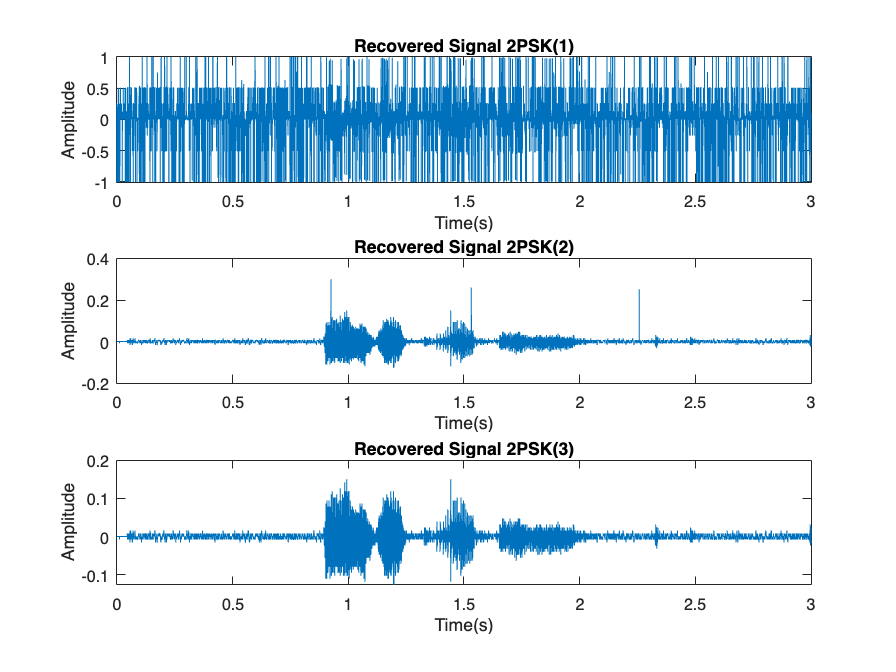

clf;

t = 0 : 1/Fs : (length(recovered1_2psk)-1)/Fs;

% 2PSK - 5dB
subplot(311)
plot(t,recovered1_2psk); title('Recovered Signal 2PSK(1)'); xlabel('Time(s)'); ylabel('Amplitude');

% 2PSK - 10dB
subplot(312)
plot(t,recovered2_2psk); title('Recovered Signal 2PSK(2)'); xlabel('Time(s)'); ylabel('Amplitude');

% 2PSK - 70dB
subplot(313)
plot(t,recovered3_2psk); title('Recovered Signal 2PSK(3)'); xlabel('Time(s)'); ylabel('Amplitude');

####  PLOT OF 16PSK

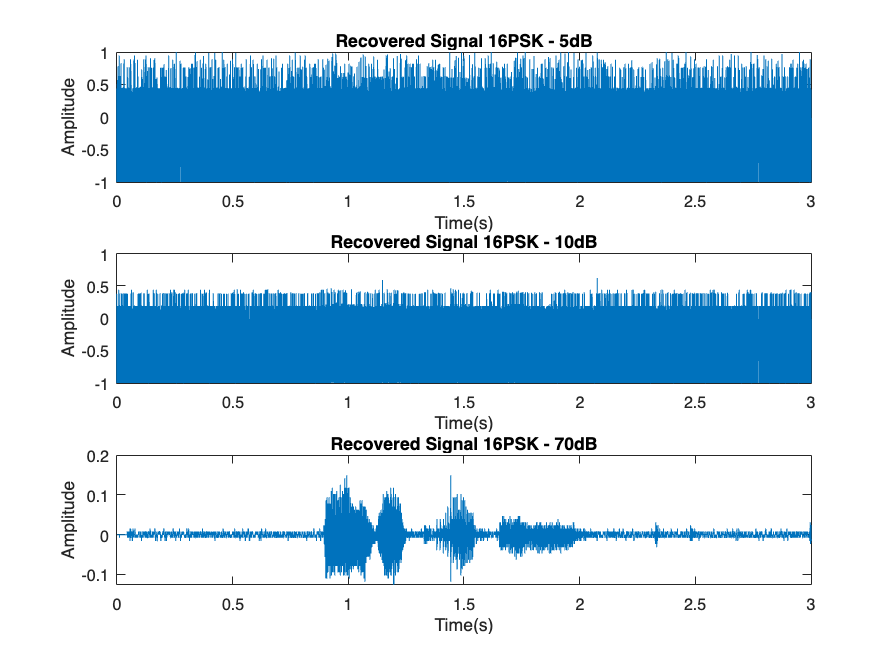

t = 0 : 1/Fs : (length(recovered1_16psk)-1)/Fs;
clf;
% 16PSK - 5dB
subplot(311)
plot(t,recovered1_16psk); title('Recovered Signal 16PSK - 5dB'); xlabel('Time(s)'); ylabel('Amplitude');
% 16PSK - 10dB
subplot(312)
plot(t,recovered2_16psk); title('Recovered Signal 16PSK - 10dB'); xlabel('Time(s)'); ylabel('Amplitude');
% 16PSK - 70dB
subplot(313)
plot(t,recovered3_16psk); title('Recovered Signal 16PSK - 70dB'); xlabel('Time(s)'); ylabel('Amplitude');

####  PLOT OF 4FSK

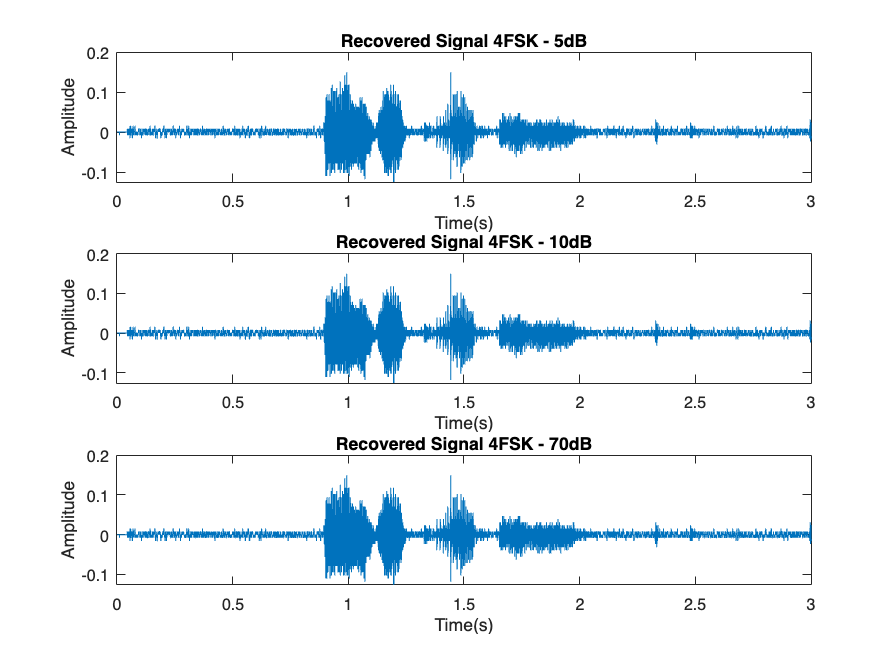

t = 0 : 1/Fs : (length(recovered1_4fsk)-1)/Fs;
clf;
% 4FSK - 5dB
subplot(311)
plot(t,recovered1_4fsk); title('Recovered Signal 4FSK - 5dB'); xlabel('Time(s)'); ylabel('Amplitude'); 
% 4FSK - 10dB
subplot(312)
plot(t,recovered2_4fsk); title('Recovered Signal 4FSK - 10dB'); xlabel('Time(s)'); ylabel('Amplitude');
% 4FSK - 70dB
subplot(313)
plot(t,recovered3_4fsk); title('Recovered Signal 4FSK - 70dB'); xlabel('Time(s)'); ylabel('Amplitude');

#### PLOT OF 4QAM

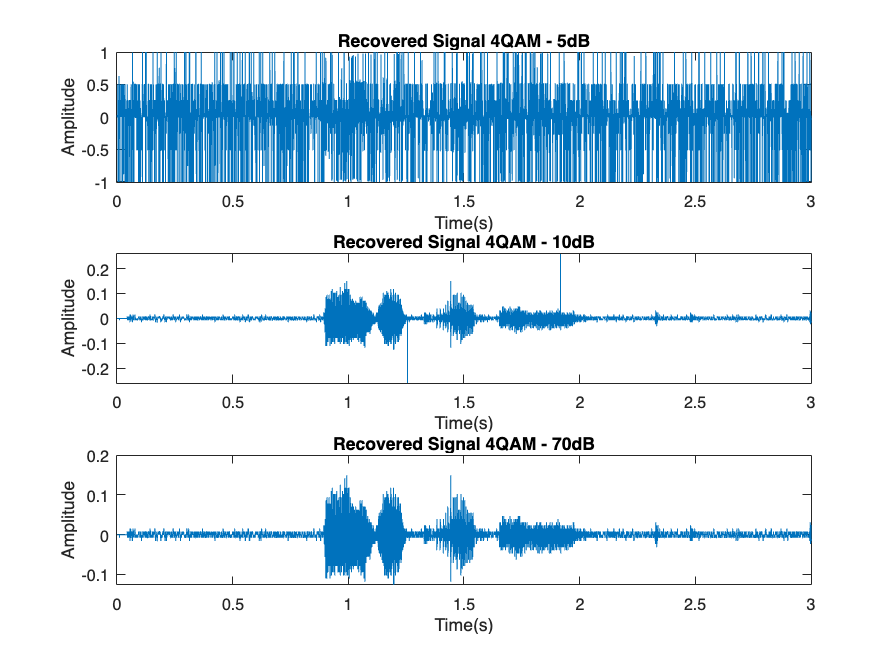

t = 0 : 1/Fs : (length(recovered1_4qam)-1)/Fs;
clf;
% 4QAM - 5dB
subplot(311)
plot(t,recovered1_4qam); title('Recovered Signal 4QAM - 5dB'); xlabel('Time(s)'); ylabel('Amplitude'); 
% 4QAM - 10dB
subplot(312)
plot(t,recovered2_4qam); title('Recovered Signal 4QAM - 10dB'); xlabel('Time(s)'); ylabel('Amplitude');
% 4QAM - 70dB
subplot(313)
plot(t,recovered3_4qam); title('Recovered Signal 4QAM - 70dB'); xlabel('Time(s)'); ylabel('Amplitude');

####  PLOT OF 8QAM

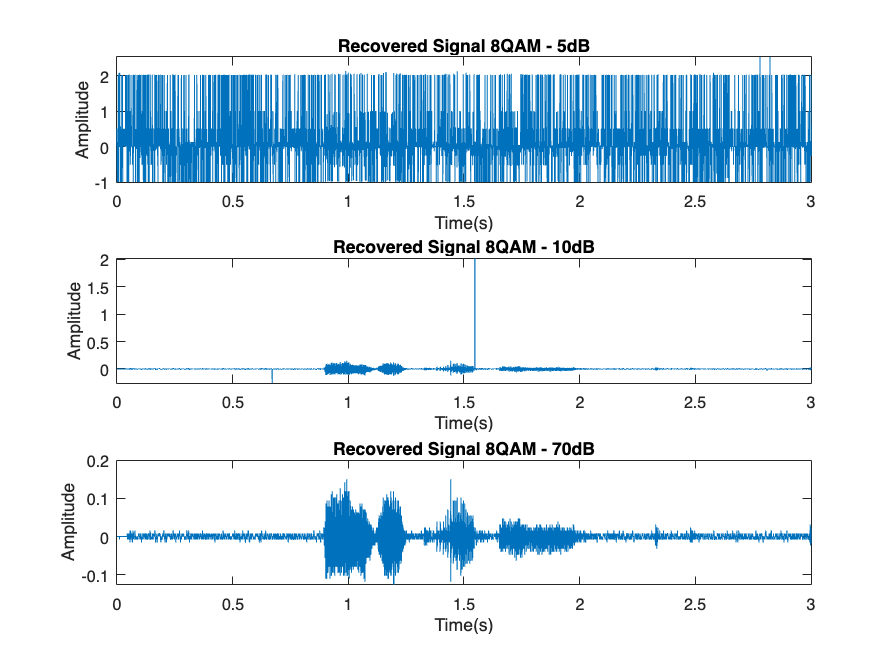

t = 0 : 1/Fs : (length(recovered1_8qam)-1)/Fs;
clf;
% 8QAM - 5dB
subplot(311)
plot(t,recovered1_8qam); title('Recovered Signal 8QAM - 5dB'); xlabel('Time(s)'); ylabel('Amplitude'); 
% 8QAM - 10dB
subplot(312)
plot(t,recovered2_8qam); title('Recovered Signal 8QAM - 10dB'); xlabel('Time(s)'); ylabel('Amplitude');
% 8QAM - 70dB
subplot(313)
plot(t,recovered3_8qam); title('Recovered Signal 8QAM - 70dB'); xlabel('Time(s)'); ylabel('Amplitude');

####   PLOT OF 16QAM

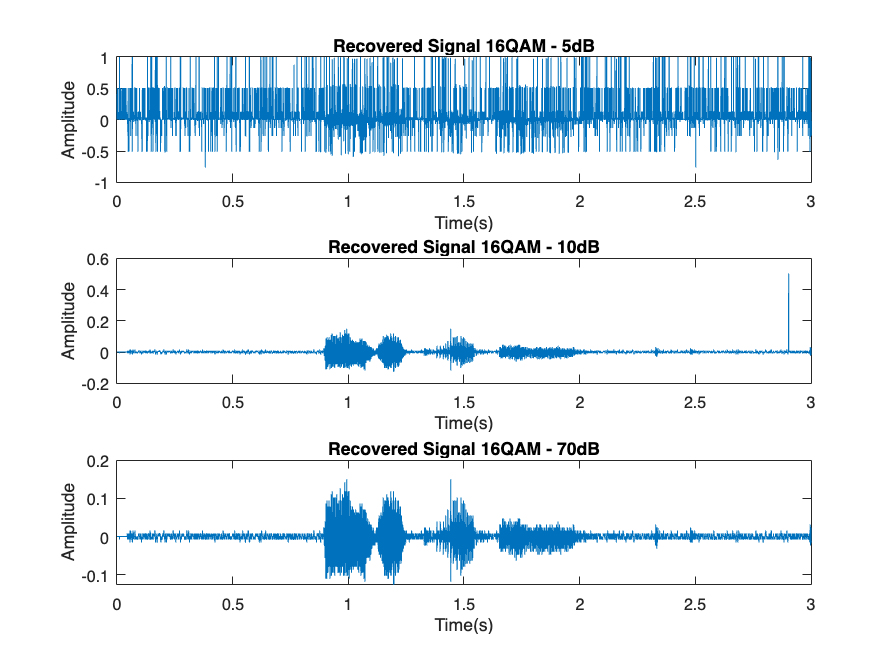

t = 0 : 1/Fs : (length(recovered1_16qam)-1)/Fs;
clf;
% 16QAM - 5dB
subplot(311)
plot(t,recovered1_16qam); title('Recovered Signal 16QAM - 5dB'); xlabel('Time(s)'); ylabel('Amplitude'); 
% 16QAM - 10dB
subplot(312)
plot(t,recovered2_16qam); title('Recovered Signal 16QAM - 10dB'); xlabel('Time(s)'); ylabel('Amplitude');
% 16QAM - 70dB
subplot(313)
plot(t,recovered3_16qam); title('Recovered Signal 16QAM - 70dB'); xlabel('Time(s)'); ylabel('Amplitude');